Problem 1

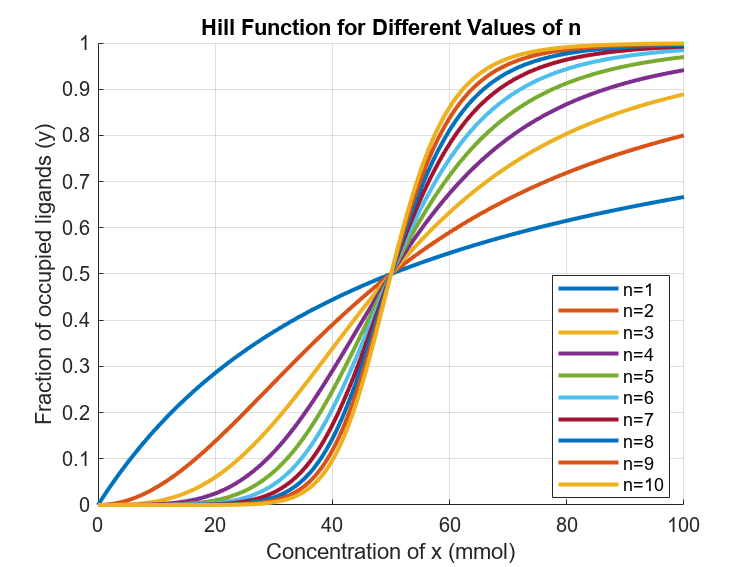

k = 50; % mmol
x = linspace(0, 100, 1000); 
n_val = 1:10;

y = zeros(length(x), length(n_val));
for i = 1:length(n_val)
    n = n_val(i);
    y(:, i) = x.^n ./ (k^n + x.^n);
end

figure;
hold on;
for i = 1:length(n_val)
    plot(x, y(:, i), 'LineWidth', 2);
end
hold off;

title('Hill Function for Different Values of n');
xlabel('Concentration of x (mmol)');
ylabel('Fraction of occupied ligands (y)');
legend('n=1', 'n=2', 'n=3', 'n=4', 'n=5', 'n=6', 'n=7', 'n=8', 'n=9', 'n=10', "Location", "best");
grid on;

saveas(gcf, 'hill_function_plot.pdf');

Problem 3

tspan = 1:100

tspan =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


r_val = [-1/2, -1/8, 1, -1/8, -1/2]

r_val =    -0.5000   -0.1250    1.0000   -0.1250   -0.5000



r1 = linspace(r_val(1),r_val(1), 20)

r1 =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000


r2 = linspace(r_val(2),r_val(2), 20)

r2 =    -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250


r3 = linspace(r_val(3),r_val(3), 20)

r3 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


r4 = linspace(r_val(4),r_val(4), 20)

r4 =    -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250


r5 = linspace(r_val(5),r_val(5), 20)

r5 =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000



r_group = [r1, r2, r3, r4, r5]

r_group =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



[t1, x1] = ode23(@(t,x) r(1)*x + x.^3 - x.^5, 1:20, 1);
[t2, x2] = ode23(@(t,x) r(2)*x + x.^3 - x.^5, 21:40, x1(20,1));
[t3, x3] = ode23(@(t,x) r(3)*x + x.^3 - x.^5, 41:60, x2(20,1));
[t4, x4] = ode23(@(t,x) r(4)*x + x.^3 - x.^5, 61:80, x3(20,1));
[t5, x5] = ode23(@(t,x) r(5)*x + x.^3 - x.^5, 81:100, x4(20,1));

x_group = [x1', x2', x3', x4', x5']

x_group =     1.0000    0.7307    0.5631    0.4084    0.2743    0.1742    0.1075    0.0655    0.0398    0.0241    0.0146    0.0089    0.0054    0.0033    0.0020    0.0012    0.0007    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0008    0.0021    0.0058    0.0158    0.0429    0.1171


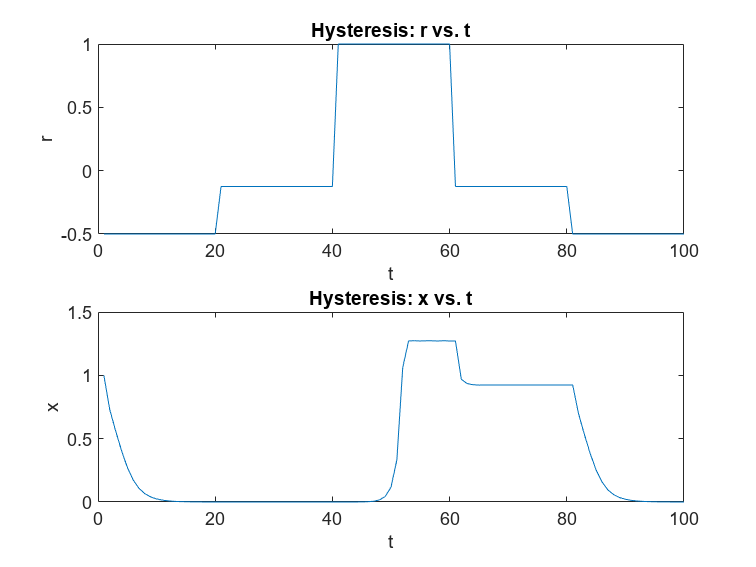


subplot(2,1,1);
plot(tspan, r_group);
title("Hysteresis: r vs. t")
xlabel("t")
ylabel("r")

subplot(2,1,2);
plot(tspan, x_group);
title("Hysteresis: x vs. t")
xlabel("t")
ylabel("x")